# Visual Inspection Pre-processing Techniques

Explore different data preprationh techniques that may be used as part of a visual inspection workflow.

## Matching Image Lighting

Images captured in different lighting can make object detection and classification challenging. We can automate lighting correction using [`imhistmatch`](https://www.mathworks.com/help/images/ref/imhistmatch.html).

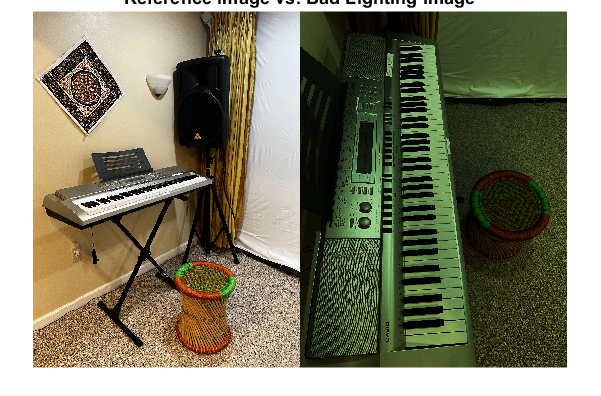

im_Reference = imread("LightingReference.jpg");


% Select an image to read in
im_BadLighting = "GreenTint.jpg";
im_BadLighting = imread(im_BadLighting);

imshowpair(im_Reference, im_BadLighting, "montage")
title("Reference Image vs. Bad Lighting Image")

** To do: **Use `imhistmatch` to correct the lighting in the image. Name the variable "im_Corrected"

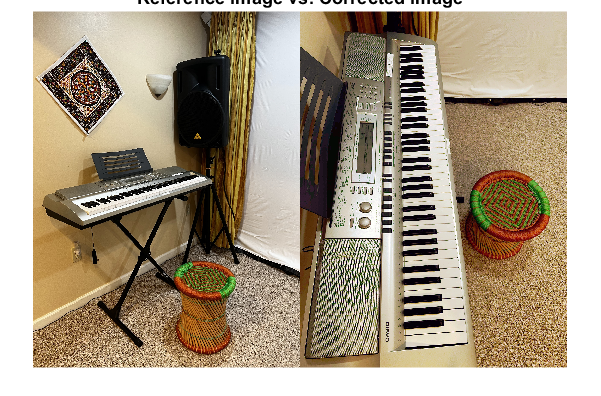

% ADD CODE HERE


imshowpair(im_Reference, im_Corrected, "montage")
title("Reference Image vs. Corrected Image")

## Image Registration

Image registration makes it easier to compare images from different captures, imaging modalities, or across time. [One approach](https://www.mathworks.com/help/images/approaches-to-registering-images.html) to registration is to **detect, extract, and match** features from two images and then calculate a geometric transform.

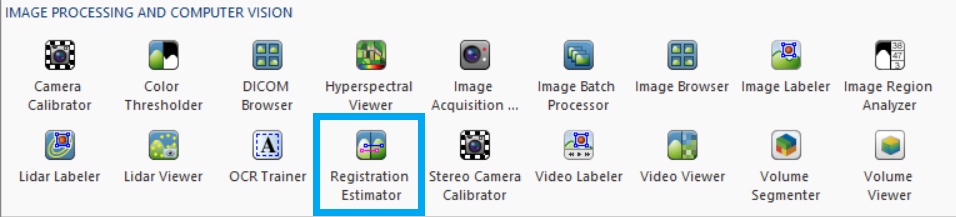

We will do this programmatically; however, this entire workflow can be done using the Registration Estimator app.

Load and view the two images.

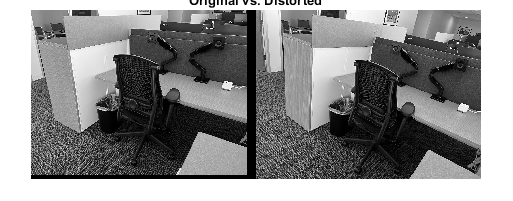

im_reference = rgb2gray(imread("ReferenceImage.JPG"));
im_distorted = rgb2gray(imread("MovingImage.JPG"));

imshowpair(im_reference, im_distorted, "montage");
title("Original vs. Distorted")

**Detect** features in both images.

fp_reference = detectSURFFeatures(im_reference);
fp_distorted = detectSURFFeatures(im_distorted);

disp("Code Run Successfully")

Code Run Successfully


**Extract** features from both images.

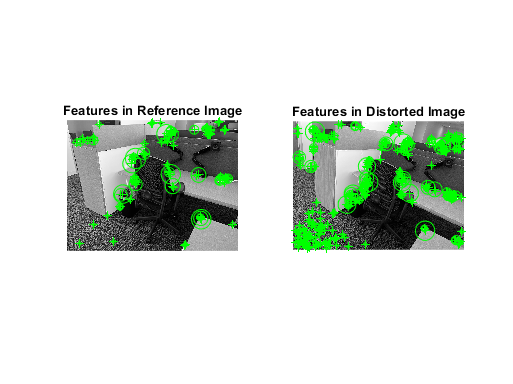

[f_reference, fp_reference] = extractFeatures(im_reference, fp_reference);
[f_distorted, fp_distorted] = extractFeatures(im_distorted, fp_distorted);

plotImagePair(im_reference, im_distorted, ...
    "Features in Reference Image", "Features in Distorted Image", ...
    fp_reference, fp_distorted);

**Match **features between images.

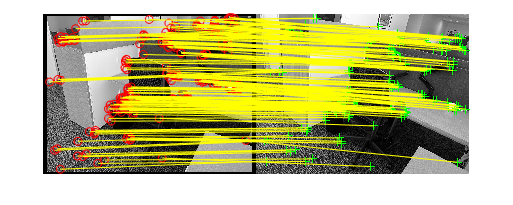

% Adjust the slider to see how the max ratio affects the number of feature
% points 

f_matching = matchFeatures(f_reference, f_distorted, "MaxRatio", 0.25);

fp_matching_reference = fp_reference(f_matching(:,1),:); 
fp_matching_distorted = fp_distorted(f_matching(:,2),:);

figure;
title("Matching Feature Points (Inludes Outliers)")

showMatchedFeatures(im_reference, im_distorted, ...
    fp_matching_reference, fp_matching_distorted, ...
    "montage");

Calculate Geometric Transform.

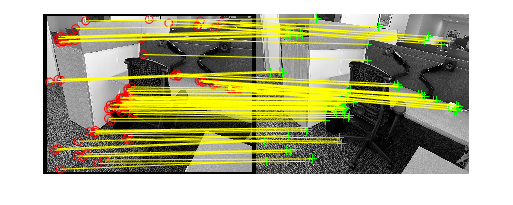

[tform,inlierIdx] = estimateGeometricTransform2D(fp_matching_distorted, fp_matching_reference, "projective");

fp_inlier_reference = fp_matching_reference(inlierIdx);
fp_inlier_distorted = fp_matching_distorted(inlierIdx);

figure;
title("Matching Feature Points (No Outliers)")

showMatchedFeatures(im_reference, im_distorted, ...
    fp_inlier_reference, fp_inlier_distorted, "montage");

Apply transform and show recovered image.

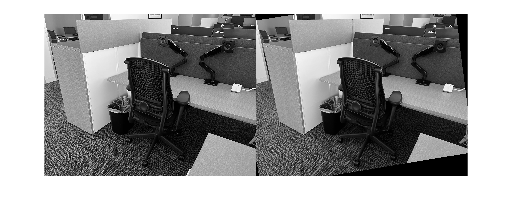

outputView = imref2d(size(im_reference));
im_recovered = imwarp(im_distorted,tform,"OutputView",outputView);

figure;
title("Original vs. Recovered")

imshowpair(im_reference, im_recovered, "montage")

## Image Segmentation

Sometimes, you may have multiple objects of interest in an image that you want to segment out. We will use an image with multiple images of pills and crop each pill out. These cropped images will be used as training data for a deep network in the next exercise.

selectImage = "chip1.jpg"

selectImage = "chip1.jpg"

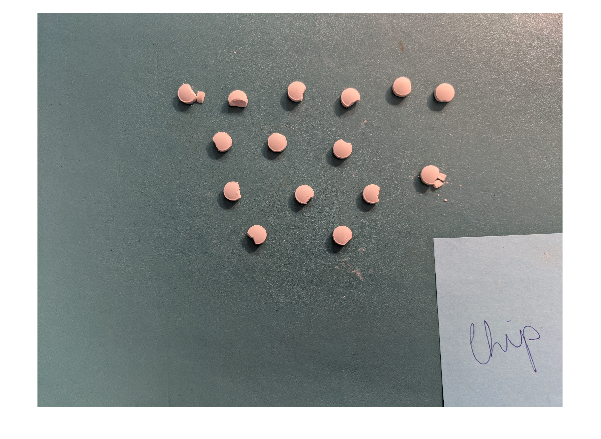

im = imread(selectImage);
figure; imshow(im)

Detect pills in foregroud using [`imfindciricles`](https://www.mathworks.com/help/images/ref/imfindcircles.html)

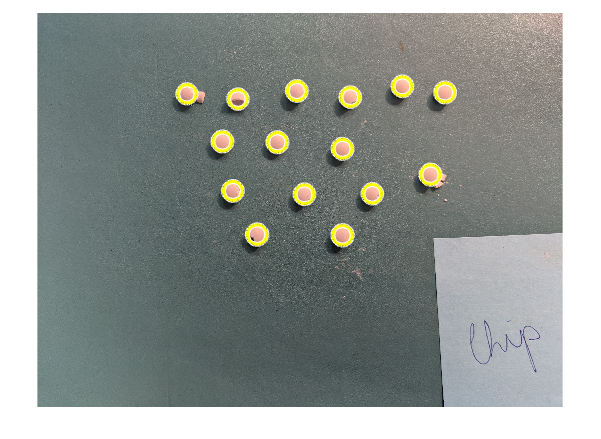

% Drag the slider to adjust the sensitivity (Best = 0.9)

[centers,radii,~] = imfindcircles(im,[35 100], ...
    'ObjectPolarity','bright', ...
    'Sensitivity',0.9);

figure; imshow(im)
viscircles(centers,radii,"Color","yellow");a

Crop images to create training data (used for next exercise).

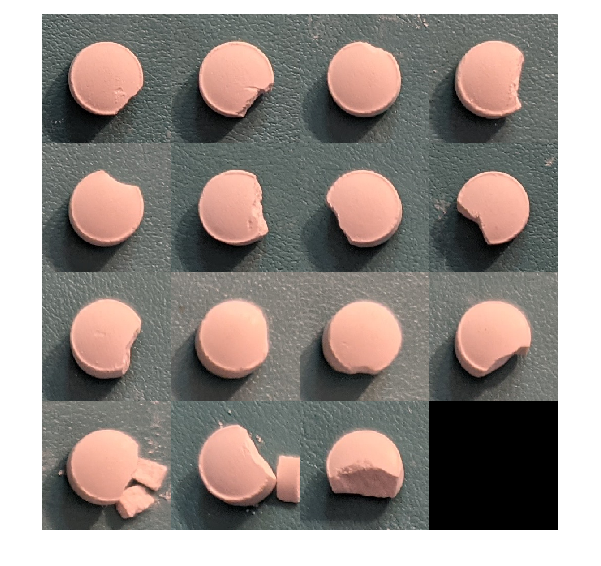

imageArray = {};

for i = 1:length(radii)
    xMin = centers(i,1) - 1.75*radii(i);
    yMin = centers(i,2) - 1.75*radii(i);
    cropDim = 3.5*radii(i);

    imageArray{i} = imcrop(im,[xMin, yMin, cropDim, cropDim]); 
end

figure; montage(imageArray)

## Summary

This section covered the following preprocessing steps:

- Matching image lighting with `imhistmatch`

- Performing image registration using automatic feature point detection

- Using segmentation to detect multiple objects in an image

Many image processing techniques can be done through apps in the Image Processing Toolbox. You can try these out in your desktop version of MATLAB.

*Copyright 2022 The MathWorks, Inc.*